# Modelo de la mitocondria cardiaca

## Autor: Ines Thiele

## Traduccion: German Preciat

En este tutorial trabajaremos con el modelo de la mitocondria cardíaca humana. Usaremos COBRA Toolbox para analizar las propiedades de la red del modelo de la mitocondria. Este modelo tiene 235 metabolitos, 225 reacciones y 323 genes. Repetiremos ciertas simulaciones simples como se describe en la información complementaria proporcionada por Orth et al${\;}^1$. Además, volveremos a ejecutar las simulaciones en Thiele et al${\;}^2$.

Para comenzar primero inicializamos COBRA Toolbox y cambiamos de directorio a donde esta el modelo de la mitocondria

initCobraToolbox



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2024
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.39.3).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.


 > Configuring solver environment variables ...
   - [----] ILOG_CPLEX_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [----] GUROBI_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [----] TOMLAB_PATH: --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [*---] MOSEK_PATH: /Applications/Mosek/10.2/
   Done.
 > Checking available solvers and solver interfaces ...Gurobi installed at this location? 
Licence file current? 


changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of ibm_cplex, so it cannot be tested
Could not find installation of tomlab_cplex, so it cannot be tested
ϰ
License cannot be located. The default search path is ':/Users/eduardoruiz/mosek/mosek.lic:'.

MSK_RES_ERR_MISSING_LICENSE_FILE

 > [matlab] Primal optimality condition in solveCobraLP satisfied.
   --------------------------------------------------------
   pdco.m                      Version pdco5 of 15 Jun 2018
   Primal-dual barrier method to minimize a convex function
   subject to linear constraints Ax + r = b,  bl <= x <= bu
                                                           
   Michael Saunders       SOL and ICME, Stanford University
   Contributors:     Byunggyoo Kim (SOL), Chris Maes (ICME)
                     Santiago Akle (ICME), Matt Zahr (ICME)
                     Aekaansh Verma (ME)                   
   -------

changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of cplexlp, so it cannot be tested
Could not find installation of tomlab_snopt, so it cannot be tested
 Done.
 > Setting default solvers ... Done.
 > Saving the MATLAB path ... Done.
   - The MATLAB path was saved in the default location.

 > Summary of available solvers and solver interfaces

			Support 	   LP 	 MILP 	   QP 	 MIQP 	  NLP 	   EP
	------------------------------------------------------------------------------
	gurobi       	active        	    0 	    0 	    0 	    0 	    - 	    -
	ibm_cplex    	active        	    0 	    0 	    0 	    0 	    - 	    -
	tomlab_cplex 	active        	    0 	    0 	    0 	    0 	    - 	    -
	glpk         	active        	    1 	    1 	    - 	    - 	    - 	    -
	mosek        	active        	    1 	    - 	    1 	    - 	    - 	    1
	matlab       	active        	    1 	    - 	    - 	    - 	    1 	    -

selpath = uigetdir(pwd, 'Selecciona el directorio con el modelo de la mitocondria');
cd(selpath)

## Simulaciones a realizar:

- Cálculo del flujo a través de `DM_ATP` en condiciones aeróbicas

- Cálculo del flujo a través de `DM_ATP` en condiciones anaeróbicas

- Cálculo del flujo a través de `DM_ATP` a partir de precursores de energía alternativa

- Cálculo del flujo a través de la producción de cofactores

- Cálculo de soluciones óptimas alternas

- Cálculo de la robustez de la red

- Análisis del plano de fase fenotípica

- Simulación de knockouts de genes

- Practica

## Procedimiento:

### 1. Cálculo del flujo a través de DM_ATP en condiciones aeróbicas

El modelo proporcionado es la mitocondria del corazón de los mamíferos, por lo tanto, el objetivo principal de este sistema es producir energía para varias funciones fisiológicas del corazón y el cuerpo humano en general. La reacción de demanda de ATP dentro del modelo (`DM_ATP`) es una reacción que implica la hidrólisis de ATP a ADP, Pi y protones en el citosol. Fijaremos esta reacción como nuestro objetivo. A partir de entonces, proporcionaremos glucosa y oxígeno en grandes cantidades y calcularemos el flujo a través de la demanda de ATP. 

Fijar los límites inferior y superior del intercambio de glucosa a 20 mmol/gDW/hr. 

El flujo de consumo de oxígeno debe de ser básicamente ilimitado. 

El flujo a través de la reacción de demanda de ATP (solucion.f) debe de ser alto (1000 mmol/gDW/hr).

load('CardicMitochondriaIT.mat');
modelMito = model;
modelMito = changeRxnBounds(modelMito, 'EX_glc(e)', -20, 'b'); 
modelMito = changeRxnBounds(modelMito, 'EX_o2(e)', -1000, 'l'); 
modelMito = changeObjective(modelMito, 'DM_atp(c)'); 
FBAaerobic = optimizeCbModel(modelMito, 'max');
display('El flujo a través de la reacción de demanda de ATP es de: ')

El flujo a través de la reacción de demanda de ATP es de: 


FBAaerobic.f 

ans = NaN

### 2. Cálculo del flujo a través de DM_ATP en condiciones anaeróbicas

Para ejecutar esta simulación, restringiremos la absorción de oxígeno fijando el límite inferior de la reacción de intercambio de oxígeno.

En comparación con la condición aeróbica, la condición anaeróbica debe de reducir el flujo a través de la demanda de ATP, lo que significa la necesidad de oxígeno para ejecutar la fosforilación oxidativa.

modelanaerobic = model;
modelanaerobic = changeRxnBounds(modelanaerobic, 'EX_glc(e)', -20, 'b'); 
modelanaerobic = changeRxnBounds(modelanaerobic, 'EX_o2(e)', 0, 'l'); 
modelanaerobic = changeObjective(modelanaerobic, 'DM_atp(c)');
FBAanaerobic = optimizeCbModel(modelanaerobic, 'max')

FBAanaerobic = struct with fields:
    origStatText: []
               f: 40
              f0: NaN
              f1: 40
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'matlab'
       algorithm: 'default'
            stat: 1
        origStat: 1
            time: 0.0029
           basis: []
          vars_v: []
               x: [225×1 double]


display('El flujo a través de la reacción de demanda de ATP es de: ')

El flujo a través de la reacción de demanda de ATP es de: 


FBAanaerobic.f 

ans = 40

### 3. Cálculo del flujo a través de DM_ATP a partir de precursores de energía alternativa

Para calcular el flujo a través de la demanda de ATP a partir de precursores de energía alternativa, primero cerramos las fuentes de metabolitos importantes. Estos son representados como reacciones de intercambio (`EX_`).

`EX_co2 <=> `(Consumo o produccion de dioxido de carbono)

Metabolitos importantes:

exchanges = {'EX_12dgr_m(e)';  
'EX_acac(e)'; 
'EX_arachd(e)'; 
'EX_co2(e)'; 
'EX_coa(e)'; 
'EX_crvnc(e)'; 
'EX_cys-L(e)'; 
'EX_fe2(e)'; 
'EX_glc(e)'; 
'EX_glu-L(e)'; 
'EX_gly(e)'; 
'EX_glyc(e)'; 
'EX_glyc3p(e)'; 
'EX_hb(e)'; 
'EX_hdca(e)'; 
'EX_lac-L(e)'; 
'EX_ocdca(e)'; 
'EX_ocdcea(e)'; 
'EX_ocdcya(e)'; 
'EX_pi(e)'; 
'EX_ps_m(e)';
'EX_urea(e)';}

exchanges = 22×1 cell array
    {'EX_12dgr_m(e)'}
    {'EX_acac(e)'   }
    {'EX_arachd(e)' }
    {'EX_co2(e)'    }
    {'EX_coa(e)'    }
    {'EX_crvnc(e)'  }
    {'EX_cys-L(e)'  }
    {'EX_fe2(e)'    }
    {'EX_glc(e)'    }
    {'EX_glu-L(e)'  }
    {'EX_gly(e)'    }
    {'EX_glyc(e)'   }
    {'EX_glyc3p(e)' }
    {'EX_hb(e)'     }
    {'EX_hdca(e)'   }
    {'EX_lac-L(e)'  }
    {'EX_ocdca(e)'  }
    {'EX_ocdcea(e)' }
    {'EX_ocdcya(e)' }
    {'EX_pi(e)'     }
    {'EX_ps_m(e)'   }
    {'EX_urea(e)'   }


modelalter = model;
modelalter = changeRxnBounds(modelalter, exchanges, 0, 'l'); % cerramos el consumo

Ahora proporcionaremos un precursor a la vez y calcularemos el flujo a través de la demanda de ATP.

Abrir cada fuente una por una para ver el fenotipo.

%precursores de energia
precursors = {
    'EX_ocdcea(e)', 
    'EX_acac(e)', 
    'EX_hb(e)', 
    'EX_lac-L(e)', 
    'EX_arachd(e)', 
    'EX_hdca(e)', 
    'EX_glc(e)'
};

for i=1:length(precursors)
    precursor = precursors{i};
    
    % creacion de copia temporal
    modeltemp = modelalter;
    %abrir la reaccion de intercambio
    modeltemp = changeRxnBounds(modeltemp,precursor, -20, 'l');
    %Establecer la demanda de ATP como objetivo
    modeltemp = changeObjective(modeltemp,'DM_atp(c)');
    %optimizar el modelo
    FBAtemp = optimizeCbModel(modeltemp, 'max');
    %mostrar el flujo a través de la reaccion de demanda de ATP
    fprintf('El flujo a través de la reaccion de demanda de ATP con %s es de : %f\n',precursor,FBAtemp.f)

end

El flujo a través de la reaccion de demanda de ATP con EX_ocdcea(e) es de : 917.793391
El flujo a través de la reaccion de demanda de ATP con EX_acac(e) es de : -0.000000
El flujo a través de la reaccion de demanda de ATP con EX_hb(e) es de : 49.850000
El flujo a través de la reaccion de demanda de ATP con EX_lac-L(e) es de : 299.100000
El flujo a través de la reaccion de demanda de ATP con EX_arachd(e) es de : 963.966861
El flujo a través de la reaccion de demanda de ATP con EX_hdca(e) es de : 895.429790
El flujo a través de la reaccion de demanda de ATP con EX_glc(e) es de : 638.200000


De manera similar, agregue hidroxibutirato '`EX_hb(e)`', lactato '`EX_lac-L(e)`', araquidonato '`EX_arachd(e)`', palmitato '`EX_hdca(e)`' y glucosa '`EX_glc(e)`' y calcule el flujo a través Reacción de demanda de ATP.

Tenga en cuenta en qué casos el valor de flujo es el más alto y el más pequeño. Ejecutar dicho análisis sugiere la fuente de energía favorable para la red mitocondrial del corazón.

### 4. Cálculo del flujo a través de la producción de cofactores

La generación de energía celular depende de la producción de cofactores como NADH, NADPH, etc. Aquí, calcularemos el flujo a través de las reacciones de drenaje de NADH y NADPH. Tales reacciones no existen en el modelo, por lo que agregaremos estas reacciones primero (nombre: `'NADH_drain'`, formula: `'nadh(c) -> nad(c) + h(c)'`). Despues, cerrar la reacción de demanda de ATP, de modo que la energía se gaste en cualquier otro lugar. 

modelcofac = model;
modelcofac = changeRxnBounds(modelcofac, 'EX_glc(e)', -1, 'b'); 
modelcofac = changeRxnBounds(modelcofac, 'DM_atp(c)', 0, 'b'); 
modelcofac = addReaction(modelcofac, 'NADH_drain', 'nadh(c) -> nad(c) + h(c)');
modelcofac = changeObjective(modelcofac, 'NADH_drain');
FBAcofac = optimizeCbModel(modelcofac, 'max')

FBAcofac = struct with fields:
    origStatText: []
               f: 805.4809
              f0: NaN
              f1: 805.4809
              f2: NaN
               v: [226×1 double]
               y: [235×1 double]
               w: [226×1 double]
               s: [235×1 double]
          solver: 'matlab'
       algorithm: 'default'
            stat: 1
        origStat: 1
            time: 0.0064
           basis: []
          vars_v: []
               x: [226×1 double]


display('El flujo a través de la reacción de demanda de ATP es de: ')

El flujo a través de la reacción de demanda de ATP es de: 


FBAcofac.f 

ans = 805.4809

En el caso anterior, estamos analizando el drenaje de NADH en condiciones de captación de glucosa. Repita lo anterior para el drenaje de NADPH  (nombre: `'NADPH_drain'`, formula: `'nadph(c) -> nadp(c) + h(c)'`).

modelcofac2 = model;
modelcofac2 = changeRxnBounds(modelcofac2, 'EX_glc(e)',-1,'b');
modelcofac2 = changeRxnBounds(modelcofac2, 'DM_atp(c)', 0, 'b');
modelcofac2 = addReaction(modelcofac2, 'NADPH','nadph(c) -> nadp(c) + h(c)');
modelcofac2 = changeObjective(modelcofac, 'NADH_drain');
FBAcofac = optimizeCbModel(modelcofac,'max')

FBAcofac = struct with fields:
    origStatText: []
               f: 805.4809
              f0: NaN
              f1: 805.4809
              f2: NaN
               v: [226×1 double]
               y: [235×1 double]
               w: [226×1 double]
               s: [235×1 double]
          solver: 'matlab'
       algorithm: 'default'
            stat: 1
        origStat: 1
            time: 0.0030
           basis: []
          vars_v: []
               x: [226×1 double]


fprintf('El flujo a través de la reaccion de demanda de atp es %s',FBAcofac.f)

El flujo a través de la reaccion de demanda de atp es 8.054809e+02

### 5. Cálculo de soluciones óptimas alternas

En todos los ejercicios especificados anteriormente, realizamos la optimización utilizando el análisis de balance de flujo (FBA). FBA genera una de las soluciones óptimas bajo la restricción especificada para el objetivo definido. Sin embargo, la red posee muchas otras soluciones alternativas, y podemos calcular esto de la siguiente manera:

modelopt = model;
modelopt = changeRxnBounds(modelopt, 'EX_glc(e)', 0, 'l'); 
modelopt = changeRxnBounds(modelopt, 'EX_lac-L(e)', -20, 'l'); 
modelopt = changeObjective(modelopt, 'DM_atp(c)');
FBAlac = optimizeCbModel(modelopt, 'max');

modelopt = changeRxnBounds(modelopt, 'DM_atp(c)', FBAlac.f, 'b'); 
modelopt = changeObjective(modelopt, 'ME2m');
FBAsolnMin = optimizeCbModel(modelopt, 'min')

FBAsolnMin = struct with fields:
    origStatText: []
               f: 0
              f0: NaN
              f1: 0
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'matlab'
       algorithm: 'default'
            stat: 1
        origStat: 1
            time: 0.0026
           basis: []
          vars_v: []
               x: [225×1 double]


FBAsolnMax = optimizeCbModel(modelopt, 'max')

FBAsolnMax = struct with fields:
    origStatText: []
               f: 205.8105
              f0: NaN
              f1: 205.8105
              f2: NaN
               v: [225×1 double]
               y: [235×1 double]
               w: [225×1 double]
               s: [235×1 double]
          solver: 'matlab'
       algorithm: 'default'
            stat: 1
        origStat: 1
            time: 0.0023
           basis: []
          vars_v: []
               x: [225×1 double]


En el ejemplo anterior, analizamos la variabilidad de la reacción `ME2m`, es decir, la reacción de la enzima málica bajo la absorción de lactato y el flujo óptimo a través de la demanda de ATP. Tenga en cuenta que los valores `FBAsolnMin.f `y `FBAsolnMax.f` son diferentes, lo que significa que las soluciones variables de esta reacción.

Alternativamente, ejecutar `fluxVariability` en `modelopt` generará los rangos de flujo mínimo y máximo de todas las reacciones en la red. 

[FVAmin, FVAmax] = fluxVariability(modelopt, 0);

Al fijar `optPercentage` en cero, no especificamos ningún objetivo para la simulación realizada.

### 6. Cálculo de la robustez de la red

En este ejercicio, analizaremos qué tan robusta es la red frente a la reacción de demanda de ATP bajo tasas variables de consumo de glucosa cuando el consumo de oxígeno es fijo. Además, la robustez frente a la variación de la tasa de consumo de oxígeno cuando se fija el consumo de glucosa. 

#### Glucosa

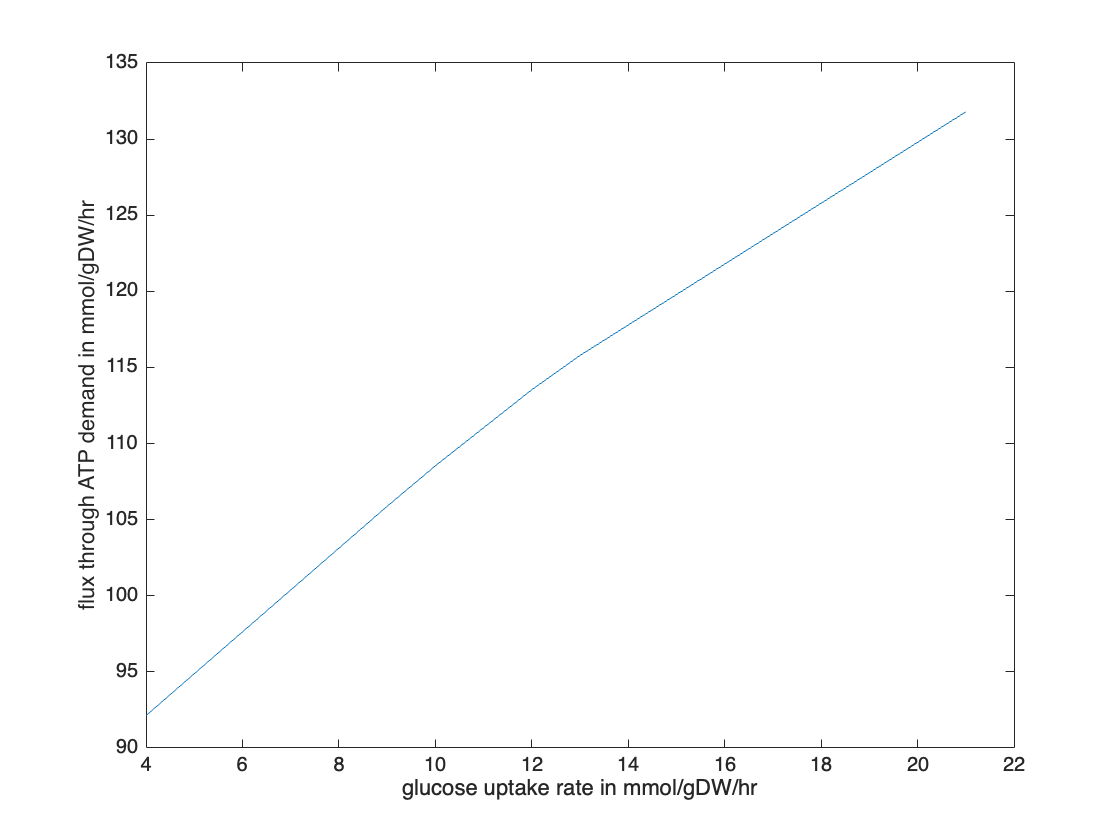

modelrobust = modelalter;
modelrobust = changeRxnBounds(modelrobust, 'EX_o2(e)', -17, 'b'); 
AtpRates = zeros(21, 1);
for i = 0:20
    modelrobust = changeRxnBounds(modelrobust, 'EX_glc(e)', -i, 'b');
    modelrobust = changeObjective(modelrobust, 'DM_atp(c)'); 
    FBArobust = optimizeCbModel(modelrobust, 'max'); 
    AtpRates(i + 1) = FBArobust.f;
end
plot(1:21, AtpRates)
xlabel('glucose uptake rate in mmol/gDW/hr')
ylabel('flux through ATP demand in mmol/gDW/hr')

#### Oxigeno

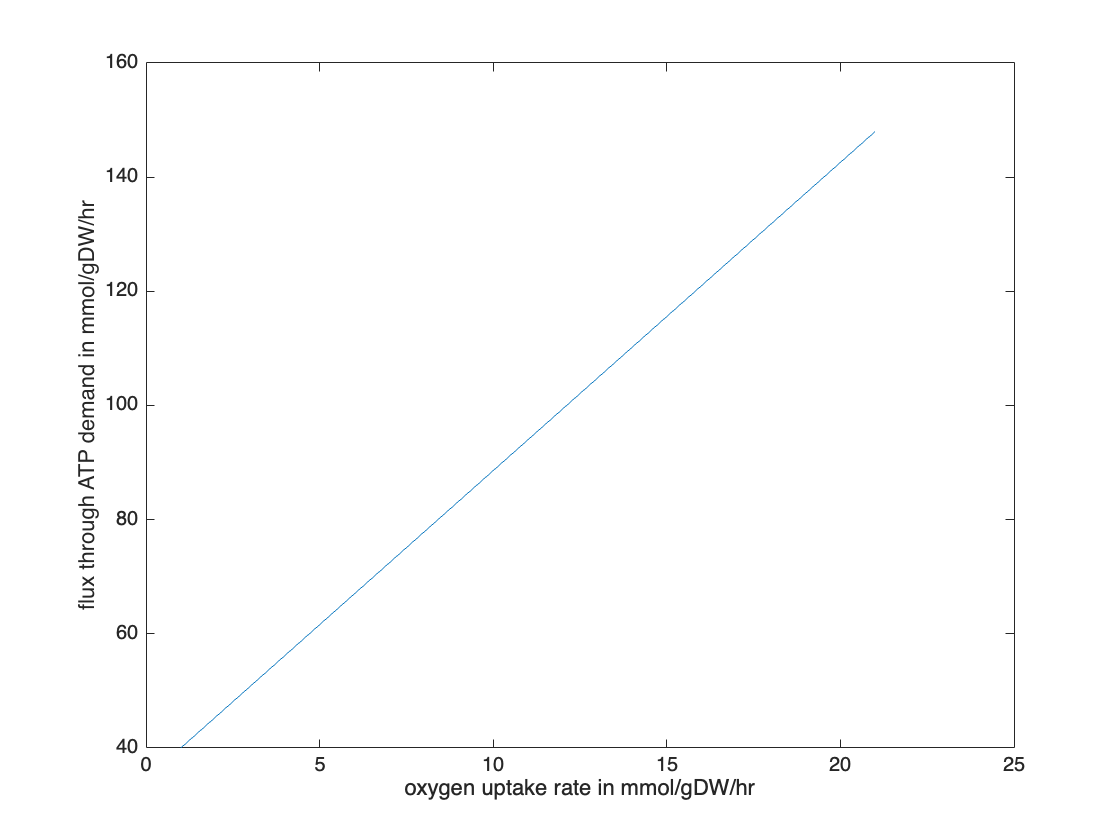

modelrobustoxy = modelalter;
modelrobustoxy = changeRxnBounds(modelrobustoxy,'EX_glc(e)', -20, 'b'); 
AtpRatesoxy = zeros(21, 1);
for i = 0:20
    modelrobustoxy = changeRxnBounds(modelrobustoxy, 'EX_o2(e)', -i, 'b'); 
    modelrobustoxy = changeObjective(modelrobustoxy, 'DM_atp(c)'); 
    FBArobustoxy = optimizeCbModel(modelrobustoxy, 'max'); 
    AtpRatesoxy(i + 1) = FBArobustoxy.f;
end
plot (1:21, AtpRatesoxy)
xlabel('oxygen uptake rate in mmol/gDW/hr') 
ylabel('flux through ATP demand in mmol/gDW/hr')

### 7. Análisis del plano de fase fenotípica

Mientras que el análisis de robustez analiza la robustez de la red variando solo un parámetro a la vez. El análisis del plano de fase fenotípica (PhPP) analiza la robustez de la red variando dos parámetros a la vez. Variaremos las tasas de consumo de glucosa y oxígeno dentro de dos bucles for y generaremos un gráfico 3D. 

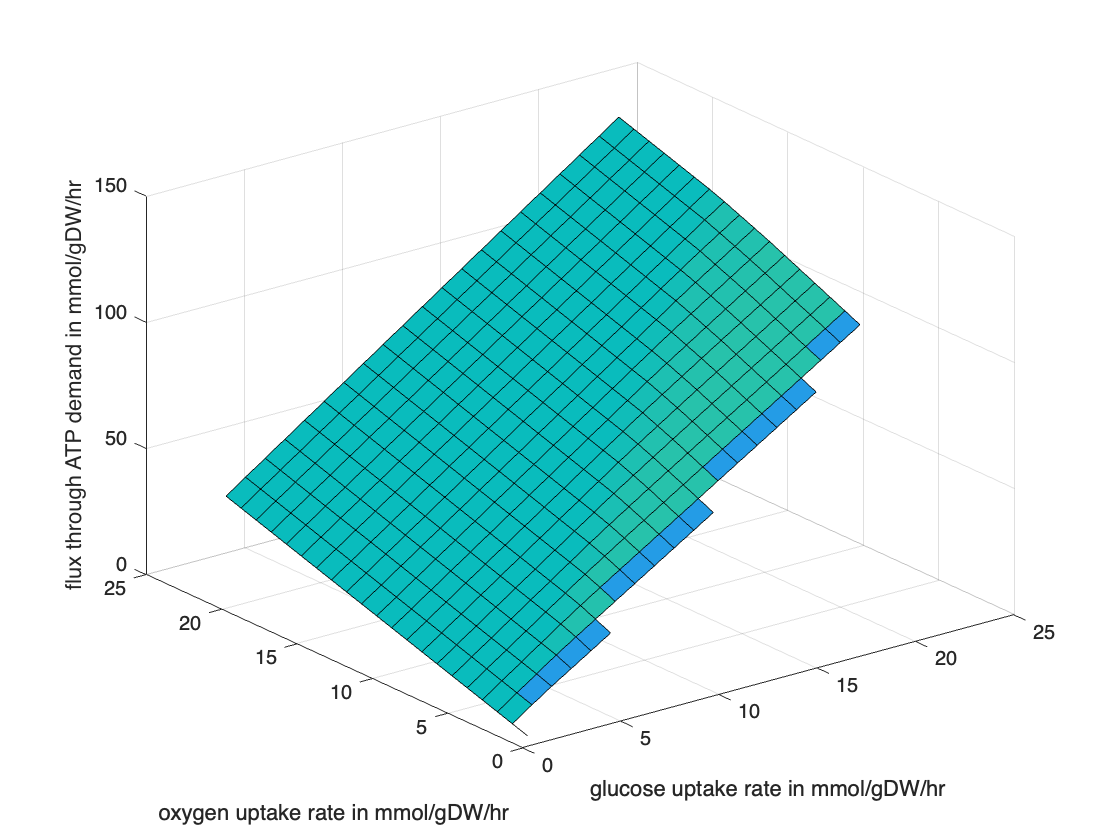

modelphpp = modelalter; 
ATPphppRates = zeros(21);
for i = 0:20
    for j = 0:20
        modelphpp = changeRxnBounds(modelphpp, 'EX_glc(e)', -i, 'b'); 
        modelphpp = changeRxnBounds(modelphpp, 'EX_o2(e)', -j, 'b'); 
        modelphpp = changeObjective(modelphpp, 'DM_atp(c)'); 
        FBAphpp = optimizeCbModel(modelphpp, 'max'); 
        ATPphppRates(i + 1,j + 1) = FBAphpp.f;
    end 
end
surfl(ATPphppRates) % 3d plot
xlabel('glucose uptake rate in mmol/gDW/hr') 

ylabel('oxygen uptake rate in mmol/gDW/hr') 
zlabel('flux through ATP demand in mmol/gDW/hr')

Plano en 2D

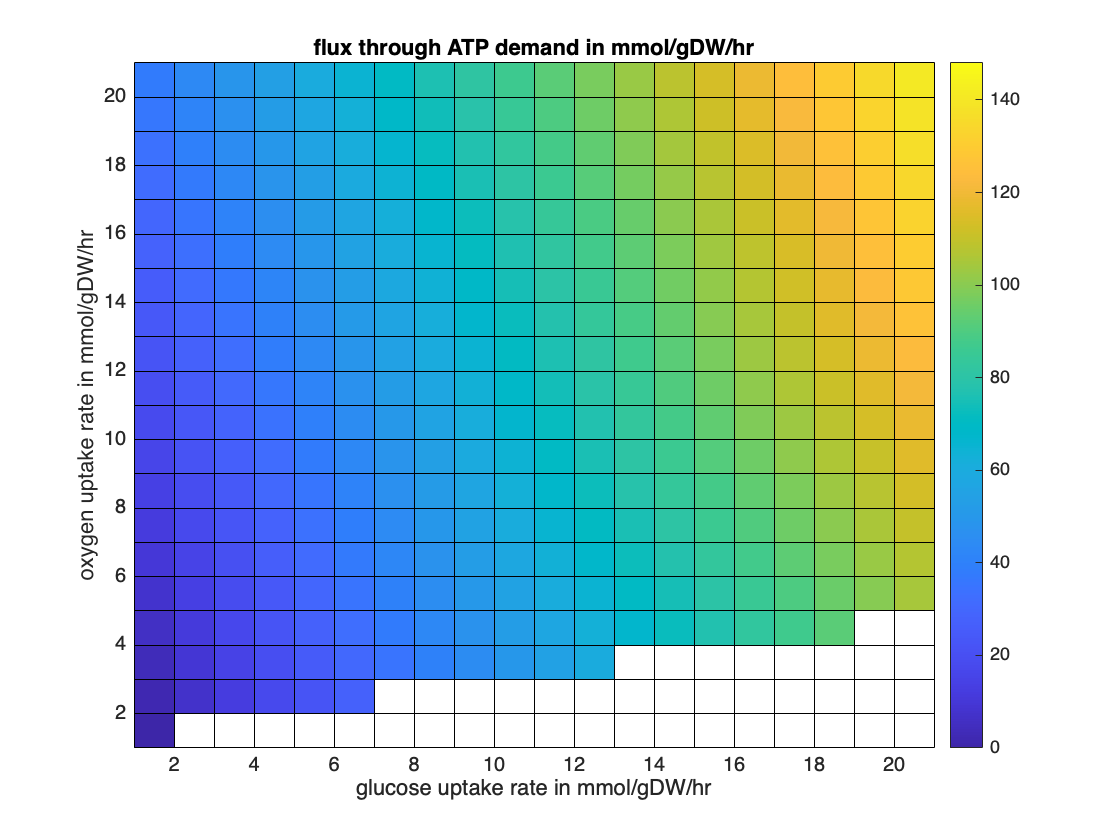

pcolor(ATPphppRates)
xlabel('glucose uptake rate in mmol/gDW/hr') 
ylabel('oxygen uptake rate in mmol/gDW/hr') 
title('flux through ATP demand in mmol/gDW/hr')
colorbar

### 8. Simulación de knockouts de genes

La realización de estudios de eliminación de genes permite el análisis de los genes knockout en el objetivo del modelo. Esto se puede hacer usando el comando `singleGeneDeletion` o el comando d`oubleGeneDeletion`. En `singleGeneDeletion`, todos los genes de la red se eliminan o las reacciones asociadas con una regla '`y`' (con la asociación GPR) con el gen especificado se limitan a estar inactivas, y se analiza el efecto en la reacción objetiva. Por el contrario, en `doubleGeneDeletion`, las eliminaciones de genes por pares están enlasadas.

Aquí, usaremos el '`DM_heme(c)`' como objetivo y realizaremos la eliminación de genes simples y dobles. 

modelknockout = model;
modelknockout = changeObjective(modelknockout, 'DM_heme(m)'); 
[grRatio, grRateKO, grRateWT, delRxnsk, hasEffect] = singleGeneDeletion_MitoModel(modelknockout);

La función (`singleGeneDeletion_MitoModel.m`) es la misma `singleGeneDeletion`, excepto que se comenta la parte de la transcripción para permitir la alineación de la solución según la matriz `model.genes`.

Analice qué genes son esenciales para la reacción '`DM_heme(c)`' a partir del output de `grRatio`. 

Para realizar la deleción de doble gen:

[grRatioDble, grRateKODble, grRateWTDble] = doubleGeneDeletion(modelknockout); 
imagesc(grRatioDble)
xlabel('gene knockout 1')
ylabel('gene knockout 2')

### 9. Practica

Se identifico experimentalmente el fenotipo de diferentes condiciones de la mitocondria entre los cuales se encuentran:

- Estado fisiológico normal

- Condición diabética

- Condición isquémica

- Dieta baja en grasas alta en glucosa

- Dieta alta en grasas baja en glucosa

#### Estado fisiológico normal

load('CardicMitochondriaIT.mat');
modelnormal = model;
modelnormal = changeRxnBounds(modelnormal,'DM_atp(c)',7.5,'l');
modelnormal = changeRxnBounds(modelnormal,'EX_acac(e)',-0.001,'l');
modelnormal = changeRxnBounds(modelnormal,'EX_acac(e)',0,'u');
modelnormal = changeRxnBounds(modelnormal,'EX_crvnc(e)',-0.156,'l');
modelnormal = changeRxnBounds(modelnormal,'EX_crvnc(e)',-0.013,'u');
modelnormal = changeRxnBounds(modelnormal,'EX_arachd(e)',-0.156,'l');
modelnormal = changeRxnBounds(modelnormal,'EX_arachd(e)',-0.013,'u');
modelnormal = changeRxnBounds(modelnormal,'EX_glc(e)',-0.875,'l');
modelnormal = changeRxnBounds(modelnormal,'EX_glc(e)',-0.525,'u');
modelnormal = changeRxnBounds(modelnormal,'EX_hb(e)',-0.001,'l');
modelnormal = changeRxnBounds(modelnormal,'EX_hb(e)',0,'u');
modelnormal = changeRxnBounds(modelnormal,'EX_hdca(e)',-1.250,'l');
modelnormal = changeRxnBounds(modelnormal,'EX_hdca(e)',-0.1,'u');
modelnormal = changeRxnBounds(modelnormal,'EX_lac-L(e)',-0.875,'l');
modelnormal = changeRxnBounds(modelnormal,'EX_o2(e)',-39.1,'l');
modelnormal = changeRxnBounds(modelnormal,'EX_o2(e)',-23.438,'u');
modelnormal = changeRxnBounds(modelnormal,'EX_ocdca(e)',-0.547,'l');
modelnormal = changeRxnBounds(modelnormal,'EX_ocdca(e)',-0.044,'u');
modelnormal = changeRxnBounds(modelnormal,'EX_ocdcea(e)',-4.141,'l');
modelnormal = changeRxnBounds(modelnormal,'EX_ocdcea(e)',-0.331,'u');
modelnormal = changeRxnBounds(modelnormal,'EX_ocdcya(e)',-0.547,'l');
modelnormal = changeRxnBounds(modelnormal,'EX_ocdcya(e)',-0.044,'u');
modelnormal = changeRxnBounds(modelnormal,'ATPtm',-32.6,'l');
modelnormal = changeRxnBounds(modelnormal,'ATPtm',32.6,'u');
modelnormal = changeRxnBounds(modelnormal,'CITRtm',-60,'l');
modelnormal = changeRxnBounds(modelnormal,'CITRtm',60,'u');
modelnormal = changeRxnBounds(modelnormal,'OCOAT1m',-16.9,'l');
modelnormal = changeRxnBounds(modelnormal,'OCOAT1m',16.9,'u');
modelnormal = changeRxnBounds(modelnormal,'SUCCt2m',-13.3,'l');
modelnormal = changeRxnBounds(modelnormal,'SUCCt2m',13.3,'u');

#### Condición diabética

modeldiab = model;
modeldiab = changeRxnBounds(modeldiab,'EX_acac(e)',-0.121,'l');
%modeldiab = changeRxnBounds(modeldiab,'EX_acac(e)',-0.020,'u');
modeldiab = changeRxnBounds(modeldiab,'EX_hb(e)',-0.106,'l');
modeldiab = changeRxnBounds(modeldiab,'EX_hb(e)',-0.016,'u');
modeldiab = changeRxnBounds(modeldiab,'EX_glc(e)',-0.644,'l');
modeldiab = changeRxnBounds(modeldiab,'EX_glc(e)',-0.386,'u');
modeldiab = changeRxnBounds(modeldiab,'C160CPT1',0.383,'l');
modeldiab = changeRxnBounds(modeldiab,'C160CPT1',0.4,'u');
modeldiab = changeRxnBounds(modeldiab,'C180CPT1',0.168,'l');
modeldiab = changeRxnBounds(modeldiab,'C180CPT1',0.183,'u');
modeldiab = changeRxnBounds(modeldiab,'C181CPT1',1.365,'l');
modeldiab = changeRxnBounds(modeldiab,'C181CPT1',1.380,'u');
modeldiab = changeRxnBounds(modeldiab,'C182CPT1',0.135,'l');
modeldiab = changeRxnBounds(modeldiab,'C182CPT1',0.151,'u');

#### Condición isquémica

modelische = model;
modelische = changeRxnBounds(modelische,'EX_o2(e)',-9.766,'l');
modelische = changeRxnBounds(modelische,'EX_o2(e)',-5.859,'u');
modelische = changeRxnBounds(modelische,'EX_glc(e)',-2,'l');
modelische = changeRxnBounds(modelische,'EX_glc(e)',-0.7,'u');
modelische = changeRxnBounds(modelische,'EX_acac(e)',-1.359,'l');
%modelische = changeRxnBounds(modelische,'EX_acac(e)',-0.140,'u');
modelische = changeRxnBounds(modelische,'EX_hb(e)',-1.171,'l');
modelische = changeRxnBounds(modelische,'EX_hb(e)',-0.110,'u');

#### Dieta baja en grasas alta en glucosa

modellowfat = model;
modellowfat = changeRxnBounds(modellowfat,'EX_glc(e)',-1.5,'l');
modellowfat = changeRxnBounds(modellowfat,'EX_glc(e)',-0.875,'u');
modellowfat = changeRxnBounds(modellowfat,'EX_arachd(e)',-0.047,'l');
modellowfat = changeRxnBounds(modellowfat,'EX_arachd(e)',-0.013,'u');
modellowfat = changeRxnBounds(modellowfat,'EX_crvnc(e)',-0.047,'l');
modellowfat = changeRxnBounds(modellowfat,'EX_crvnc(e)',-0.013,'u');
modellowfat = changeRxnBounds(modellowfat,'EX_hdca(e)',-0.375,'l');
modellowfat = changeRxnBounds(modellowfat,'EX_hdca(e)',-0.1,'u');
modellowfat = changeRxnBounds(modellowfat,'EX_ocdca(e)',-0.164,'l');
modellowfat = changeRxnBounds(modellowfat,'EX_ocdca(e)',-0.044,'u');
modellowfat = changeRxnBounds(modellowfat,'EX_ocdcea(e)',-0.521,'l');
modellowfat = changeRxnBounds(modellowfat,'EX_ocdcea(e)',-0.331,'u');
modellowfat = changeRxnBounds(modellowfat,'EX_ocdcya(e)',-0.164,'l');
modellowfat = changeRxnBounds(modellowfat,'EX_ocdcya(e)',-0.044,'u');

#### Dieta alta en grasas baja en glucosa

modelhighfat = model;
modelhighfat = changeRxnBounds(modelhighfat,'EX_glc(e)',-0.263,'l');
modelhighfat = changeRxnBounds(modelhighfat,'EX_glc(e)',-0.158,'u');
modelhighfat = changeRxnBounds(modelhighfat,'EX_arachd(e)',-0.156,'l');
modelhighfat = changeRxnBounds(modelhighfat,'EX_arachd(e)',-0.154,'u');
modelhighfat = changeRxnBounds(modelhighfat,'EX_crvnc(e)',-0.036,'l');
modelhighfat = changeRxnBounds(modelhighfat,'EX_crvnc(e)',-0.031,'u');
modelhighfat = changeRxnBounds(modelhighfat,'EX_hdca(e)',-0.467,'l');
modelhighfat = changeRxnBounds(modelhighfat,'EX_hdca(e)',-0.460,'u');
modelhighfat = changeRxnBounds(modelhighfat,'EX_ocdca(e)',-0.215,'l');
modelhighfat = changeRxnBounds(modelhighfat,'EX_ocdca(e)',-0.210,'u');
modelhighfat = changeRxnBounds(modelhighfat,'EX_ocdcea(e)',-1.179,'l');
modelhighfat = changeRxnBounds(modelhighfat,'EX_ocdcea(e)',-1.173,'u');
modelhighfat = changeRxnBounds(modelhighfat,'EX_ocdcya(e)',-0.159,'l');
modelhighfat = changeRxnBounds(modelhighfat,'EX_ocdcya(e)',-0.153,'u');
modelhighfat = changeRxnBounds(modelhighfat,'EX_acac(e)',-0.324,'l');
%modelhighfat = changeRxnBounds(modelhighfat,'EX_acac(e)',-0.287,'u');
modelhighfat = changeRxnBounds(modelhighfat,'EX_hb(e)',-0.109,'l');
modelhighfat = changeRxnBounds(modelhighfat,'EX_hb(e)',-0.076,'u');

Utilizar las herramientas usadas anteriormente para concluir algo de estos modelos

**1.Calculo de flujo de ATP en condiciones aeróbicas en las distintas condiciones**


modelos = {modelhighfat, modellowfat, modelische, modeldiab, modelnormal};
modelosNames = {'modelhighfat', 'modellowfat', 'modelische', 'modeldiab', 'modelnormal'};
% Iterar sobre cada modelo
for i = 1:length(modelos)
    model = modelos{i};

    model = changeRxnBounds(model, 'EX_glc(e)', -20, 'b'); 
    model = changeRxnBounds(model, 'EX_o2(e)', -1000, 'l');
    model = changeObjective(model, 'DM_atp(c)');
    FBAanaerobic = optimizeCbModel(model, 'max');

    % Mostrar el flujo a través de la reacción de demanda de ATP

    ATPFluxes(i) = FBAanaerobic.f;
end

figure;

colors = [ % Definir los colores en formato RGB
    0 0.4470 0.7410;  % Color para 'modelhighfat'
    0.8500 0.3250 0.0980;  % Color para 'modellowfat'
    0.9290 0.6940 0.1250;  % Color para 'modelische'
    0.4940 0.1840 0.5560;  % Color para 'modeldiab'
    0.4660 0.6740 0.1880   % Color para 'modelnormal'
];

% Crear la gráfica de barras
b = bar(ATPFluxes);
b.FaceColor= 'flat'

b =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: 'flat'
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2 3 4 5]
        YData: [888.4373 1000 1000 1000 158.9115]

  Show all properties


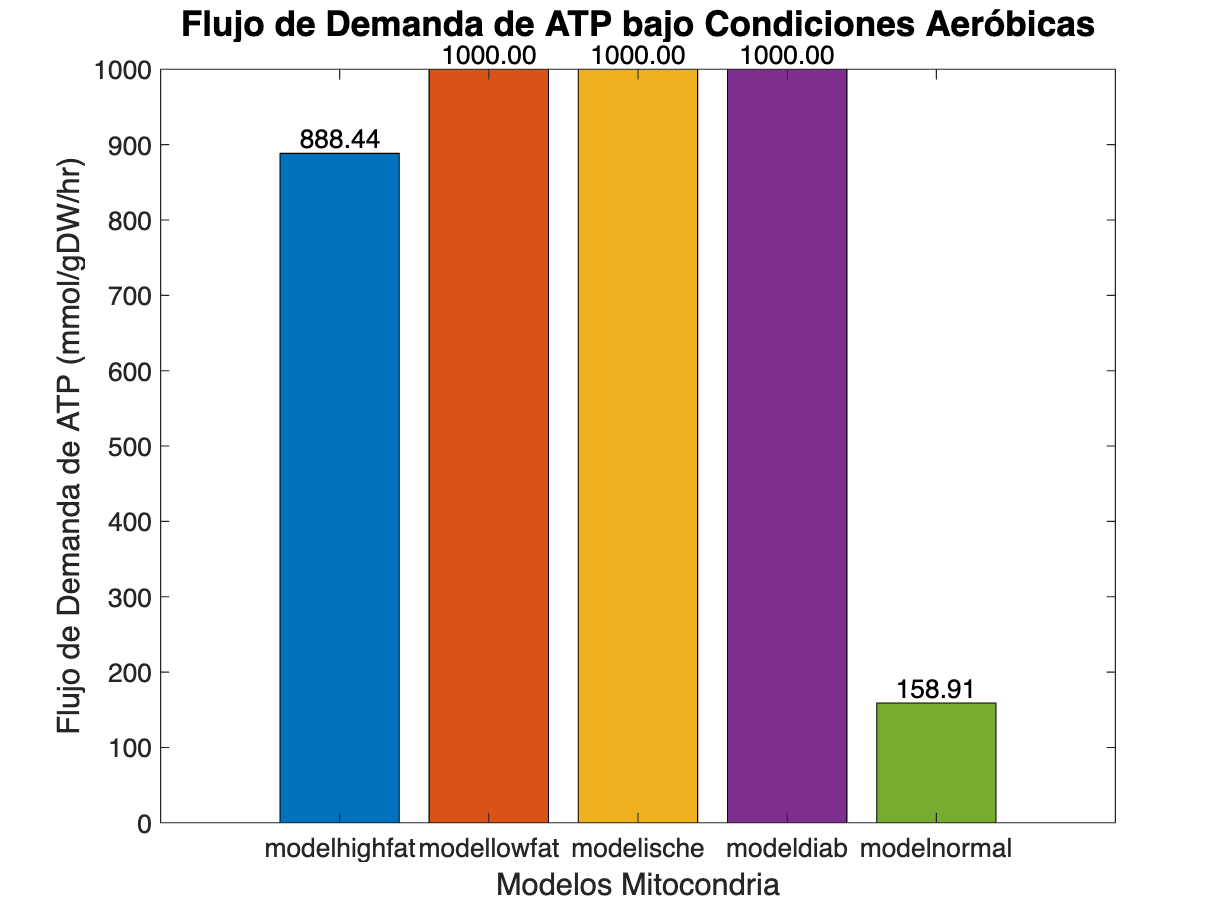

for j = 1:length(colors)
    b.CData(j,:) = colors(j,:);
end
% Añadir etiquetas de los modelos en el eje X
set(gca, 'XTickLabel', modelosNames, 'FontSize', 12);

% Añadir etiquetas y título
xlabel('Modelos Mitocondria', 'FontSize', 14);
ylabel('Flujo de Demanda de ATP (mmol/gDW/hr)', 'FontSize', 14);
title('Flujo de Demanda de ATP bajo Condiciones Anaeróbicas', 'FontSize', 16);
titleHandle = title('Flujo de Demanda de ATP bajo Condiciones Aeróbicas', 'FontSize', 16);

% Ajustar la posición del título para que no se empalme con los resultados
titlePosition = get(titleHandle, 'Position');
titlePosition(2) = titlePosition(2) + 30;  % Ajustar el valor según sea necesario
set(titleHandle, 'Position', titlePosition);
% Añadir etiquetas numéricas sobre cada barra
for i = 1:length(ATPFluxes)
    text(i, ATPFluxes(i), num2str(ATPFluxes(i), '%0.2f'), ...
        'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'FontSize', 12);
end

Los modelos de baja en grasas, isquémico y diabetico pueden producir ATP a la máxima tasa permitida mientras que el modelo de alta en grasas no alcanzó el mas alto y el modelo normal una tasa significativamente menor.

**2.Calculo de flujo de ATP en condiciones anaeróbicas en las distintas condiciones**

% Iterar sobre cada modelo
for i = 1:length(modelos)
    model = modelos{i};

    model = changeRxnBounds(model, 'EX_glc(e)', -20, 'b'); 
    model = changeRxnBounds(model, 'EX_o2(e)', -27, 'l');
    model = changeObjective(model, 'DM_atp(c)');
    FBAanaerobic = optimizeCbModel(model, 'max');

    % Mostrar el flujo a través de la reacción de demanda de ATP
    ATPFluxes2(i) = FBAanaerobic.f;  
end

figure;

% Crear la gráfica de barras
b = bar(ATPFluxes2);
b.FaceColor= 'flat'

b =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: 'flat'
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2 3 4 5]
        YData: [171.5209 184.3148 183.4837 171.3583 80.9202]

  Show all properties


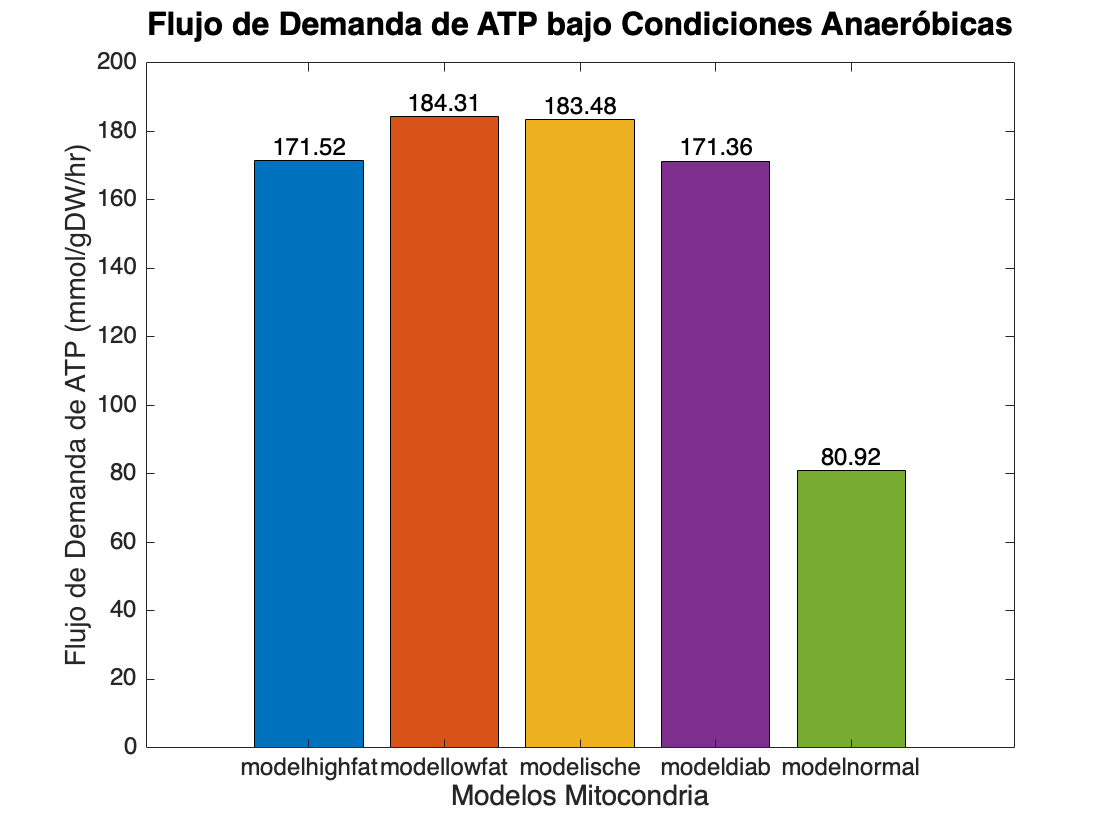

for j = 1:length(colors)
    b.CData(j,:) = colors(j,:);
end

% Añadir etiquetas de los modelos en el eje X
set(gca, 'XTickLabel', modelosNames, 'FontSize', 12);

% Añadir etiquetas y título
xlabel('Modelos Mitocondria', 'FontSize', 14);
ylabel('Flujo de Demanda de ATP (mmol/gDW/hr)', 'FontSize', 14);
title('Flujo de Demanda de ATP bajo Condiciones Anaeróbicas', 'FontSize', 16);
titleHandle = title('Flujo de Demanda de ATP bajo Condiciones Anaeróbicas', 'FontSize', 16);

% Ajustar la posición del título para que no se empalme con los resultados
titlePosition = get(titleHandle, 'Position');
titlePosition(2) = titlePosition(2) + 5;  % Ajustar el valor según sea necesario
set(titleHandle, 'Position', titlePosition);
% Añadir etiquetas numéricas sobre cada barra
for i = 1:length(ATPFluxes2)
    text(i, ATPFluxes2(i), num2str(ATPFluxes2(i), '%0.2f'), ...
        'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'FontSize', 12);
end

Los modelos no pueden encontrar soluciones viables para la producción de ATP dadas las restricciones aplicadas.

** 3.Cálculo del flujo a través de DM_ATP a partir de precursores de energía alternativa**

% Definir los nombres de los modelos y sus descripciones

% Metabolitos principales para cerrar el consumo
exchanges = {
    'EX_12dgr_m(e)';  
    'EX_acac(e)'; 
    'EX_arachd(e)'; 
    'EX_co2(e)'; 
    'EX_coa(e)'; 
    'EX_crvnc(e)'; 
    'EX_cys-L(e)'; 
    'EX_fe2(e)'; 
    'EX_glu-L(e)'; 
    'EX_gly(e)'; 
    'EX_glyc(e)'; 
    'EX_glyc3p(e)'; 
    'EX_hb(e)'; 
    'EX_hdca(e)'; 
    'EX_lac-L(e)'; 
    'EX_ocdca(e)'; 
    'EX_ocdcea(e)'; 
    'EX_ocdcya(e)'; 
    'EX_pi(e)'; 
    'EX_ps_m(e)';
    'EX_urea(e)'
};

% Precursores de energía
precursors = {
    'EX_ocdcea(e)', 
    'EX_acac(e)', 
    'EX_hb(e)', 
    'EX_lac-L(e)', 
    'EX_arachd(e)', 
    'EX_hdca(e)', 
    'EX_glc(e)'
};

% Iteracion de cada modelo y precursor
for j = 1:length(modelos)
    model = modelos{j};
    modelName = modelosNames{j};
    modelalter = model;
    modelalter = changeRxnBounds(modelalter, exchanges, 0, 'l');

    % Iterar sobre cada precursor
    for i = 1:length(precursors)
        precursor = precursors{i};
        
        % Crear una copia temporal del modelo alterado
        modeltemp = modelalter;
        
        % Abrir la reacción de intercambio para el precursor actual
        modeltemp = changeRxnBounds(modeltemp, precursor, -20, 'l');
        
        % Establecer la demanda de ATP como objetivo
        modeltemp = changeObjective(modeltemp, 'DM_atp(c)');
        
        % Optimizar el modelo
        FBAtemp = optimizeCbModel(modeltemp, 'max');
        
        % Mostrar el flujo a través de la reacción de demanda de ATP
        if isnan(FBAtemp.f)
            fprintf('El flujo a través de la reacción de demanda de ATP en %s con %s es de: NaN (no se pudo encontrar una solución factible).\n', modelName, precursor);
        else
            fprintf('El flujo a través de la reacción de demanda de ATP en %s con %s es de: %f\n', modelName, precursor, FBAtemp.f);
        end
    end
end

El flujo a través de la reacción de demanda de ATP en modelhighfat con EX_ocdcea(e) es de: NaN (no se pudo encontrar una solución factible).
El flujo a través de la reacción de demanda de ATP en modelhighfat con EX_acac(e) es de: NaN (no se pudo encontrar una solución factible).
El flujo a través de la reacción de demanda de ATP en modelhighfat con EX_hb(e) es de: NaN (no se pudo encontrar una solución factible).
El flujo a través de la reacción de demanda de ATP en modelhighfat con EX_lac-L(e) es de: NaN (no se pudo encontrar una solución factible).
El flujo a través de la reacción de demanda de ATP en modelhighfat con EX_arachd(e) es de: NaN (no se pudo encontrar una solución factible).
El flujo a través de la reacción de demanda de ATP en modelhighfat con EX_hdca(e) es de: NaN (no se pudo encontrar una solución factible).
El flujo a través de la reacción de demanda de ATP en modelhighfat con EX_glc(e) es de: NaN (no se pudo encontrar una solución factible).
El flujo a través de la r

El flujo a través de la reacción de demanda de ATP en modelische con EX_hb(e) es de: 54.424883


El flujo a través de la reacción de demanda de ATP en modelische con EX_lac-L(e) es de: NaN (no se pudo encontrar una solución factible).
El flujo a través de la reacción de demanda de ATP en modelische con EX_arachd(e) es de: NaN (no se pudo encontrar una solución factible).
El flujo a través de la reacción de demanda de ATP en modelische con EX_hdca(e) es de: NaN (no se pudo encontrar una solución factible).
El flujo a través de la reacción de demanda de ATP en modelische con EX_glc(e) es de: NaN (no se pudo encontrar una solución factible).
El flujo a través de la reacción de demanda de ATP en modeldiab con EX_ocdcea(e) es de: NaN (no se pudo encontrar una solución factible).
El flujo a través de la reacción de demanda de ATP en modeldiab con EX_acac(e) es de: NaN (no se pudo encontrar una solución factible).
El flujo a través de la reacción de demanda de ATP en modeldiab con EX_hb(e) es de: NaN (no se pudo encontrar una solución factible).
El flujo a través de la reacción de demand

El modelo isquemico es el unico capaz de producir ATP con la hemoglobina

**4.Cálculo de la robustez de la red**

#### Glucosa

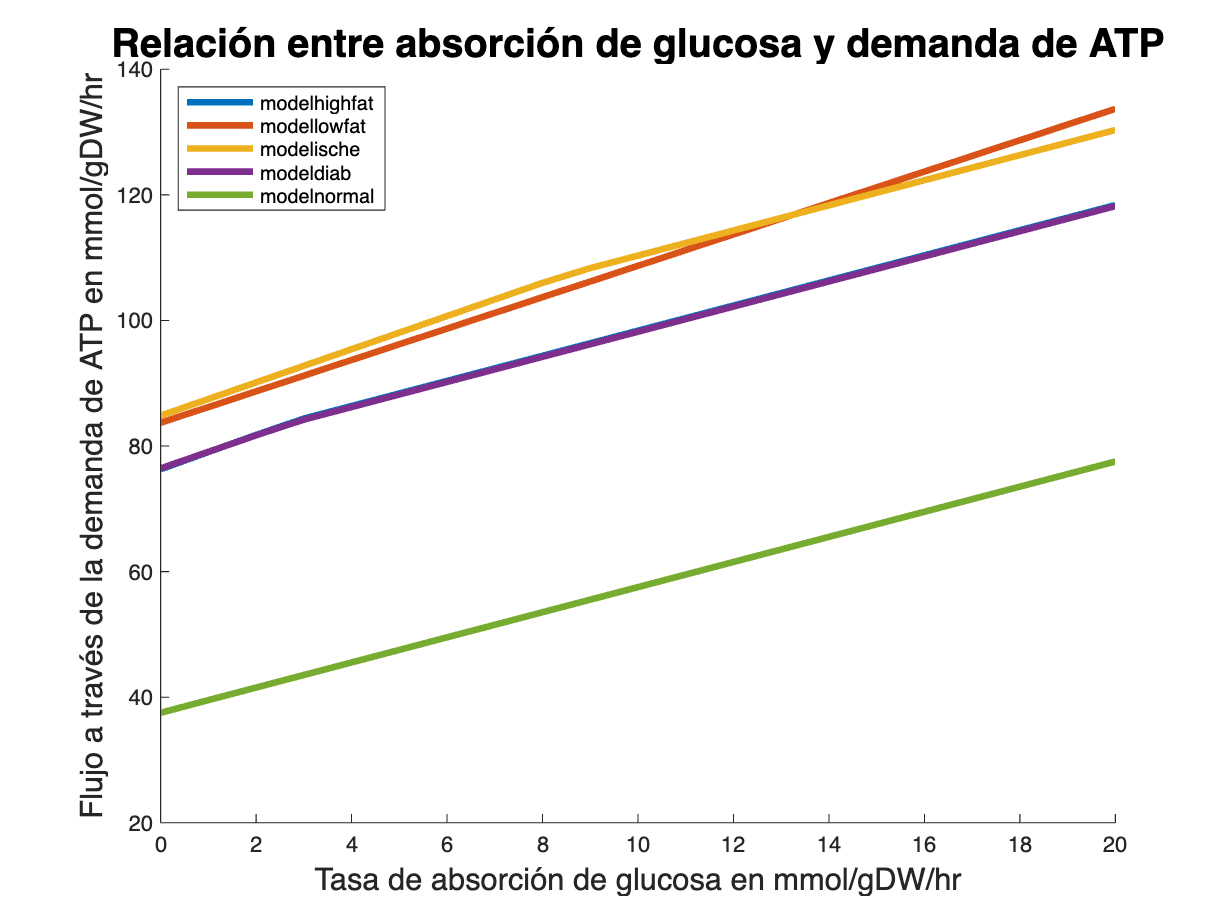


figure; 

% Iterar sobre cada modelo
for j = 1:length(modelos)
    model = modelos{j};
    modelName = modelosNames{j};
    model = changeRxnBounds(model, 'EX_o2(e)', -17, 'b'); 
    AtpRates = zeros(21, 1);
    
    % Iterar sobre diferentes tasas de absorción de glucosa
    for i = 0:20
        modeltemp = model; % Crear una copia del modelo
        modeltemp = changeRxnBounds(modeltemp, 'EX_glc(e)', -i, 'b');
        modeltemp = changeObjective(modeltemp, 'DM_atp(c)'); 
        FBArobust = optimizeCbModel(modeltemp, 'max'); 
        AtpRates(i + 1) = FBArobust.f;
    end
    
    % Graficar la tasa de ATP en función de la tasa de absorción de glucosa
    hold on;
    plot(0:20, AtpRates, 'DisplayName', modelName, 'LineWidth',3);
end

xlabel('Tasa de absorción de glucosa en mmol/gDW/hr',FontSize=14);
ylabel('Flujo a través de la demanda de ATP en mmol/gDW/hr',FontSize=14);
legend('show', 'Location', 'northwest');
title('Relación entre absorción de glucosa y demanda de ATP',FontSize=18);
hold off;

El flujo a través de la demanda de ATP varia entre los distintos modelos:

-La condición normal presenta un incremento demanda de ATP de 37.5 mmol/dDW/hr a 77 mmol/dDW/hr 

-La condición diabetica y alta en grasas presentan el mismo comportamiento  siendo 76.43 mmol/dDW/hr el punto mas bajo y 118 mmol/dDW/hr el punto mas alto

-La condición baja en grasas y alta en glucosa un incremento demanda de ATP de 83.7 mmol/dDW/hr a 133 mmol/dDW/hr en su punto más alto, siendo este el valor mayor de producción de ATP entre los distintos modelos.

-La condición isquémica un incremento de 83 mmol/dDW/hr y 130 mmol/dDW/hr siendo la segunda mas alta

#### Oxigeno

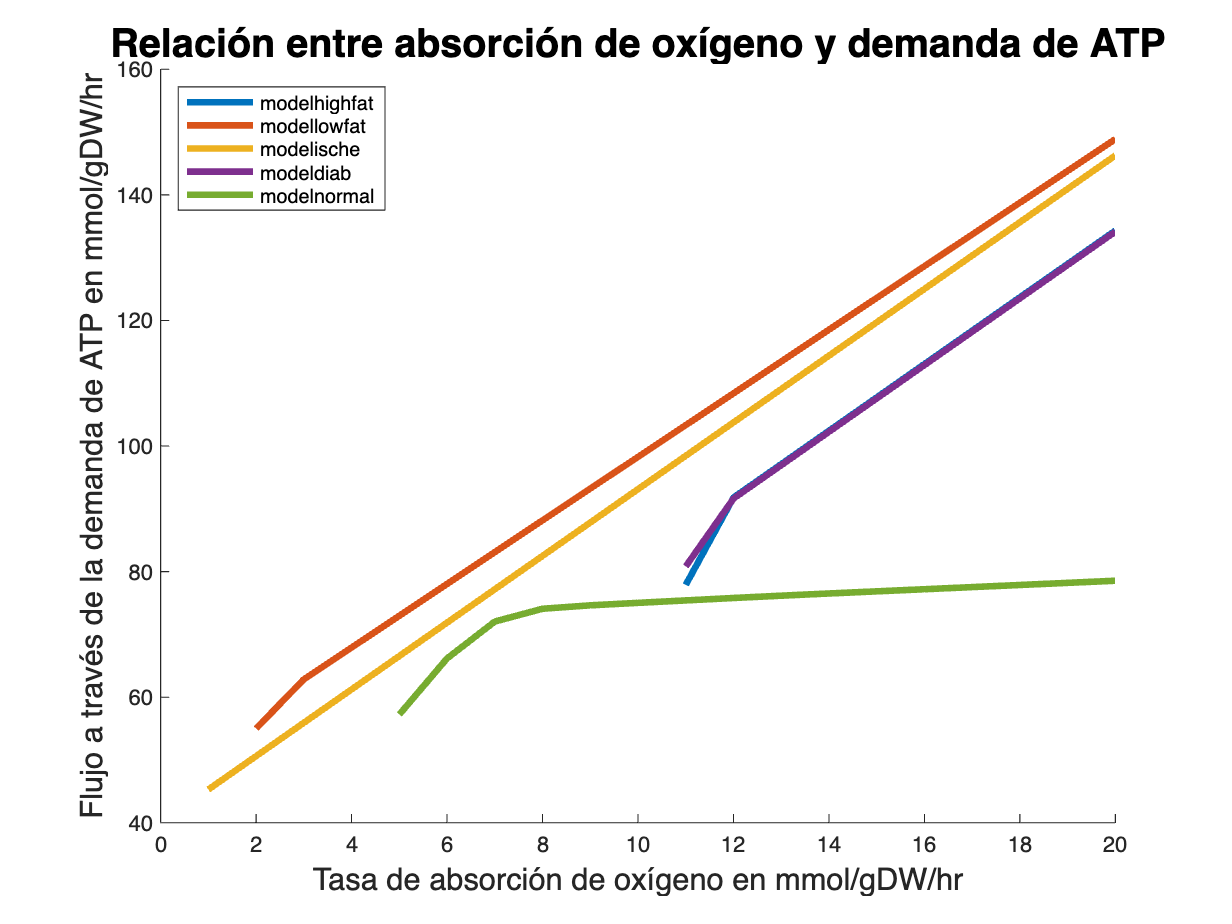

figure; 

% Iterar sobre cada modelo
for j = 1:length(modelos)
    model = modelos{j};
    modelName = modelosNames{j};
    model = changeRxnBounds(model, 'EX_glc(e)', -20, 'b'); 
    AtpRates = zeros(21, 1);
    % Iterar sobre diferentes tasas de absorción de glucosa
    for i = 0:20
        modeltemp = model; % Crear una copia del modelo
        modeltemp = changeRxnBounds(modeltemp, 'EX_o2(e)', -i, 'b');
        modeltemp = changeObjective(modeltemp, 'DM_atp(c)'); 
        FBArobust = optimizeCbModel(modeltemp, 'max'); 
        AtpRates(i + 1) = FBArobust.f;
    end
    hold on;
    plot(0:20, AtpRates, 'DisplayName', modelName, 'LineWidth',3);
end 

xlabel('Tasa de absorción de oxígeno en mmol/gDW/hr',FontSize=14);
ylabel('Flujo a través de la demanda de ATP en mmol/gDW/hr',FontSize=14);
legend('show','Location', 'northwest');
title('Relación entre absorción de oxígeno y demanda de ATP',FontSize=18);
hold off;

**5. Cálculo del flujo a través de la producción de cofactores**

% Inicializar un vector para almacenar los flujos de NADH
flujosNADH = zeros(length(modelos), 1);

% Iterar sobre cada modelo
for i = 1:length(modelos)
    model = modelos{i};
    modelName = modelosNames{i};
    
    % Restricciones de glucosa y demanda de ATP
    model = changeRxnBounds(model, 'EX_glc(e)', -1, 'b'); 
    model = changeRxnBounds(model, 'DM_atp(c)', 0, 'b'); 
    
    % Adición de la reacción de drenaje de NADH
    model = addReaction(model, 'NADH_drain', 'nadh(c) -> nad(c) + h(c)');
    
    % Reacción de drenaje de NADH como objetivo
    model = changeObjective(model, 'NADH_drain');
    FBAcofac = optimizeCbModel(model, 'max');
    
    % Almacenar el flujo a través de la reacción de drenaje de NADH
    flujosNADH(i) = FBAcofac.f;
end

% Graficar los flujos de NADH para cada modelo
figure;
b = bar(flujosNADH); % Usar un gráfico de barras para comparar los flujos
b.FaceColor= 'flat'

b =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: 'flat'
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2 3 4 5]
        YData: [499.3230 500.4208 88.4750 504.0905 255.0520]

  Show all properties


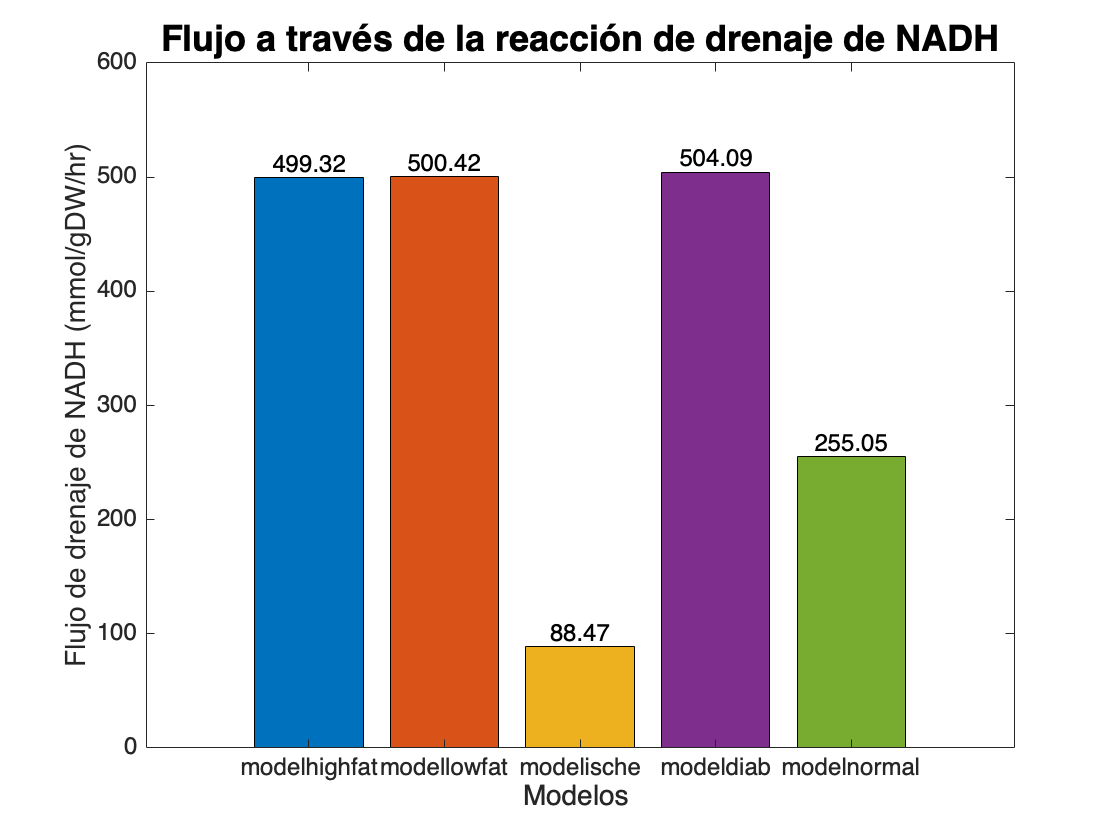

for j = 1:length(colors)
    b.CData(j,:) = colors(j,:);
end

set(gca, 'XTickLabel', modelosNames,'FontSize', 12); % Etiquetar el eje X con los nombres de los modelos
xlabel('Modelos ',FontSize=14);
ylabel('Flujo de drenaje de NADH (mmol/gDW/hr)',FontSize=14);
title('Flujo a través de la reacción de drenaje de NADH',FontSize=18);
% Añadir etiquetas con los valores sobre cada barra
for i = 1:length(flujosNADH)
    text(i, flujosNADH(i), num2str(flujosNADH(i), '%0.2f'), ...
        'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'FontSize', 12);
end

Como la eliminacion de un metabolito afecta el rendimiento del sistema, cuanto NADH puede ser eliminado del sistema.

¿Cómo el NADH puede ser eliminado del sistema y que efectos tiene en la producción del ATP?

Los modelos de bajas grasas, alta en grasas y diabeticos son los que tienen flujos de drenaje de NADH más altos a través de la reacción de drenaje de NADH mientras que el modelo isquémico y el modelo de condición normal tiene un flujo más bajo que los demás.

% Inicializar un vector para almacenar los flujos de NADPH
flujosNADPH = zeros(length(modelos), 1);

% Iterar sobre cada modelo
for i = 1:length(modelos)
    model = modelos{i};
    modelName = modelosNames{i};
    
    % Restricciones de glucosa y demanda de ATP
    model = changeRxnBounds(model, 'EX_glc(e)', -10, 'b'); 
    model = changeRxnBounds(model, 'DM_atp(c)', 0, 'b'); 
    
    % Adición de la reacción de drenaje de NADH
    model = addReaction(model, 'NADPH_drain', 'nadph(c) -> nadp(c) + h(c)');
    
    % Reacción de drenaje de NADH como objetivo
    model = changeObjective(model, 'NADPH_drain');
    FBAcofac = optimizeCbModel(model, 'max');
    
    % Almacenar el flujo a través de la reacción de drenaje de NADH
    flujosNADPH(i) = FBAcofac.f;
end

% Graficar los flujos de NADH para cada modelo
figure;
b = bar(flujosNADPH); % Usar un gráfico de barras para comparar los flujos
b.FaceColor= 'flat'

b =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: 'flat'
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [1 2 3 4 5]
        YData: [499.4575 500.1508 126.7295 503.1788 271.3498]

  Show all properties


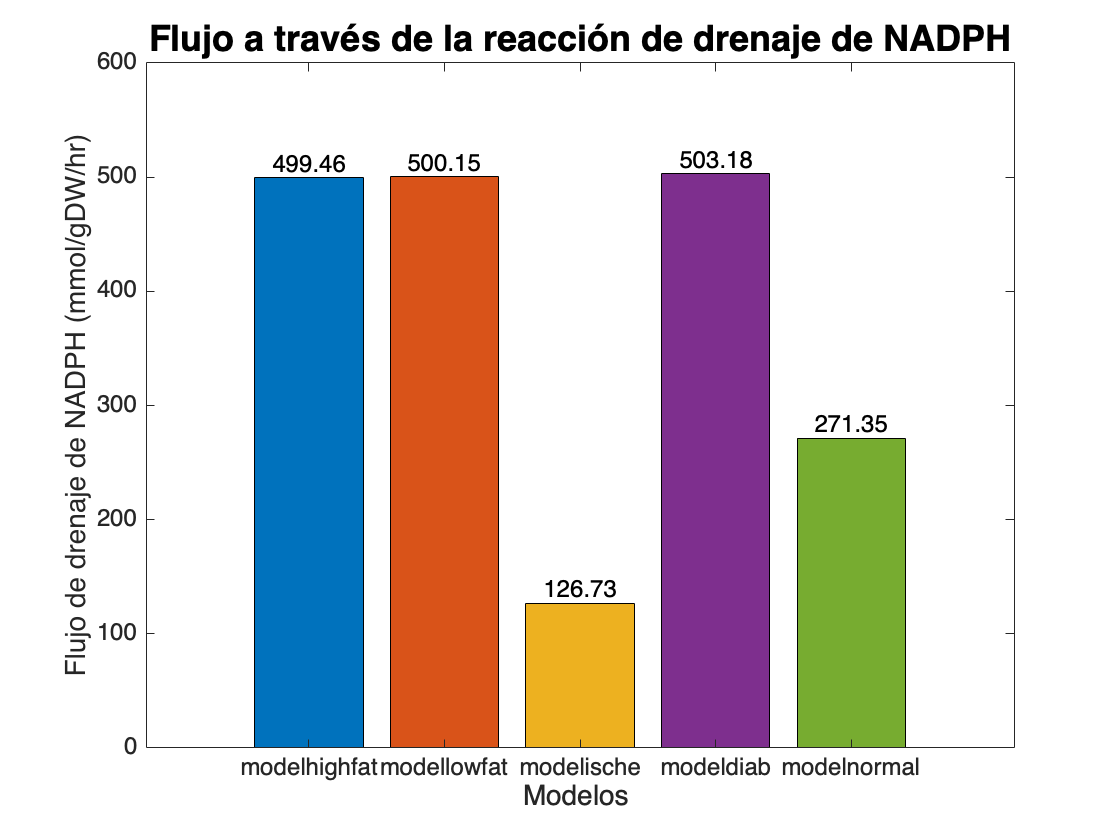


for j = 1:length(colors)
    b.CData(j,:) = colors(j,:);
end

set(gca, 'XTickLabel', modelosNames, 'FontSize', 12); % Etiquetar el eje X con los nombres de los modelos
xlabel('Modelos ',FontSize=14);
ylabel('Flujo de drenaje de NADPH (mmol/gDW/hr)',FontSize=14);
title('Flujo a través de la reacción de drenaje de NADPH',FontSize=18);
% Añadir etiquetas con los valores sobre cada barra
for i = 1:length(flujosNADPH)
    text(i, flujosNADPH(i), num2str(flujosNADPH(i), '%0.2f'), ...
        'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'FontSize', 12);
end

**6.Análisis del plano de fase fenotípica**

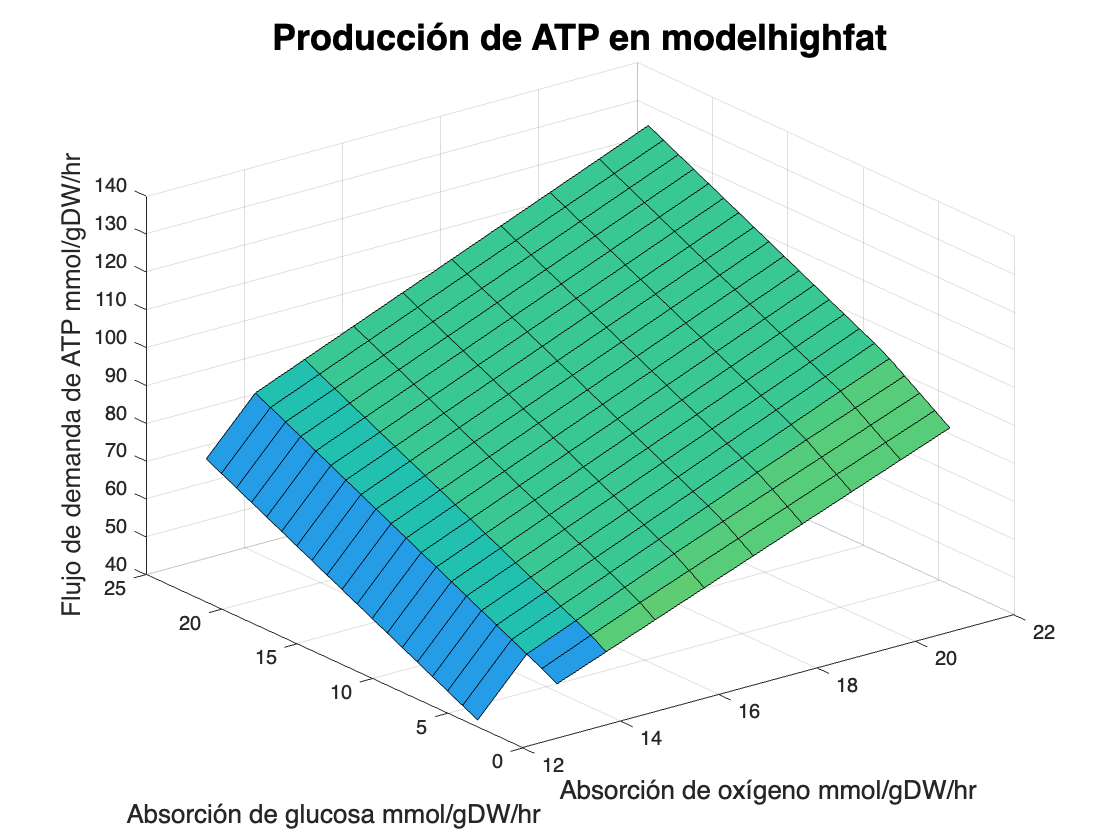

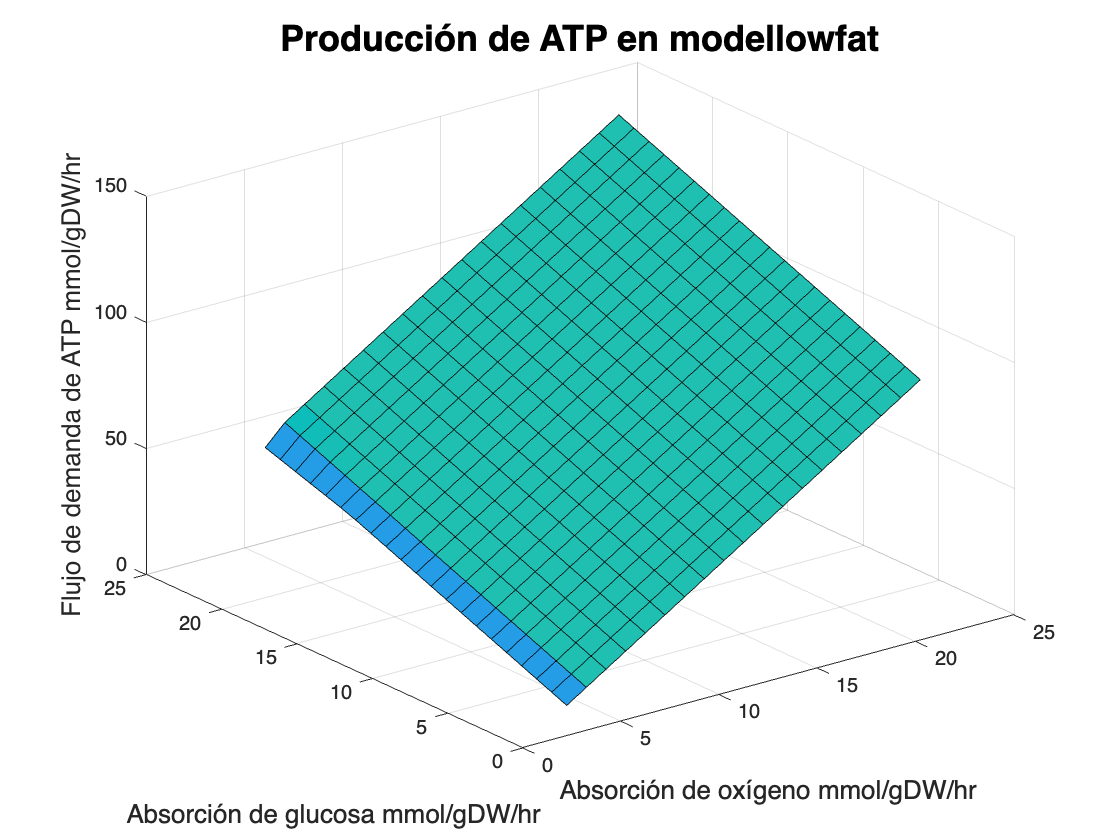

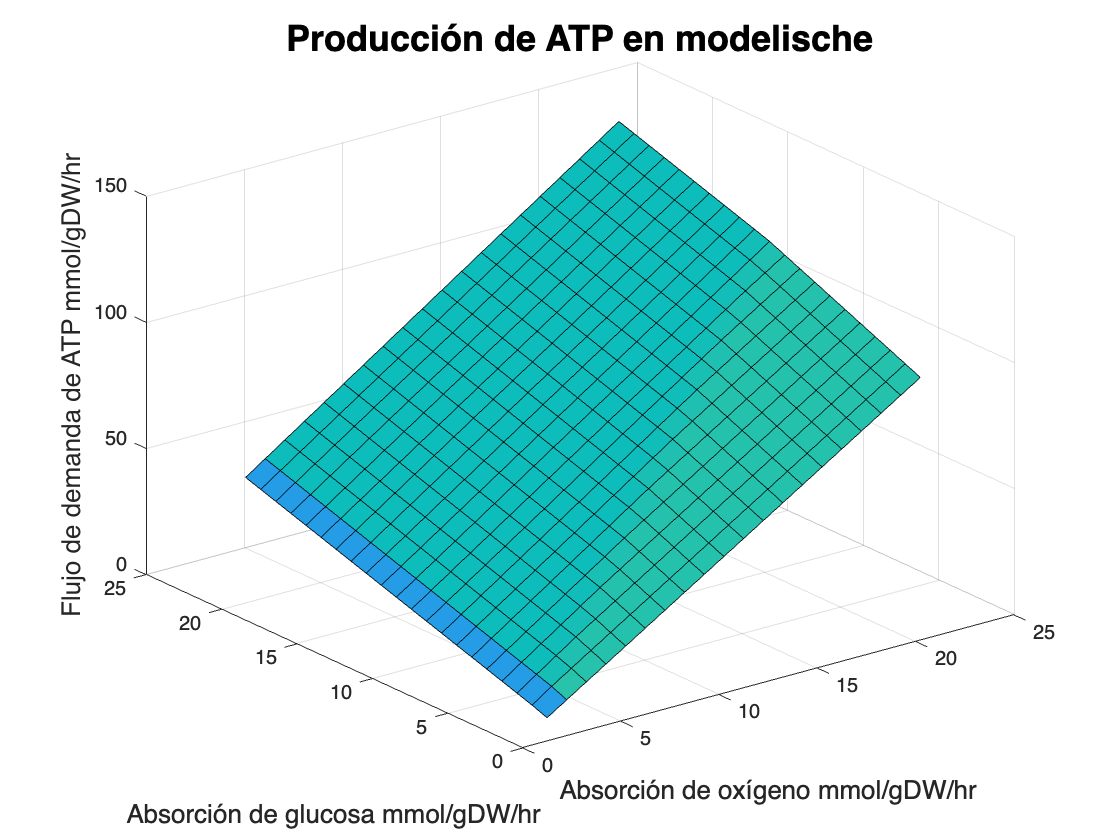

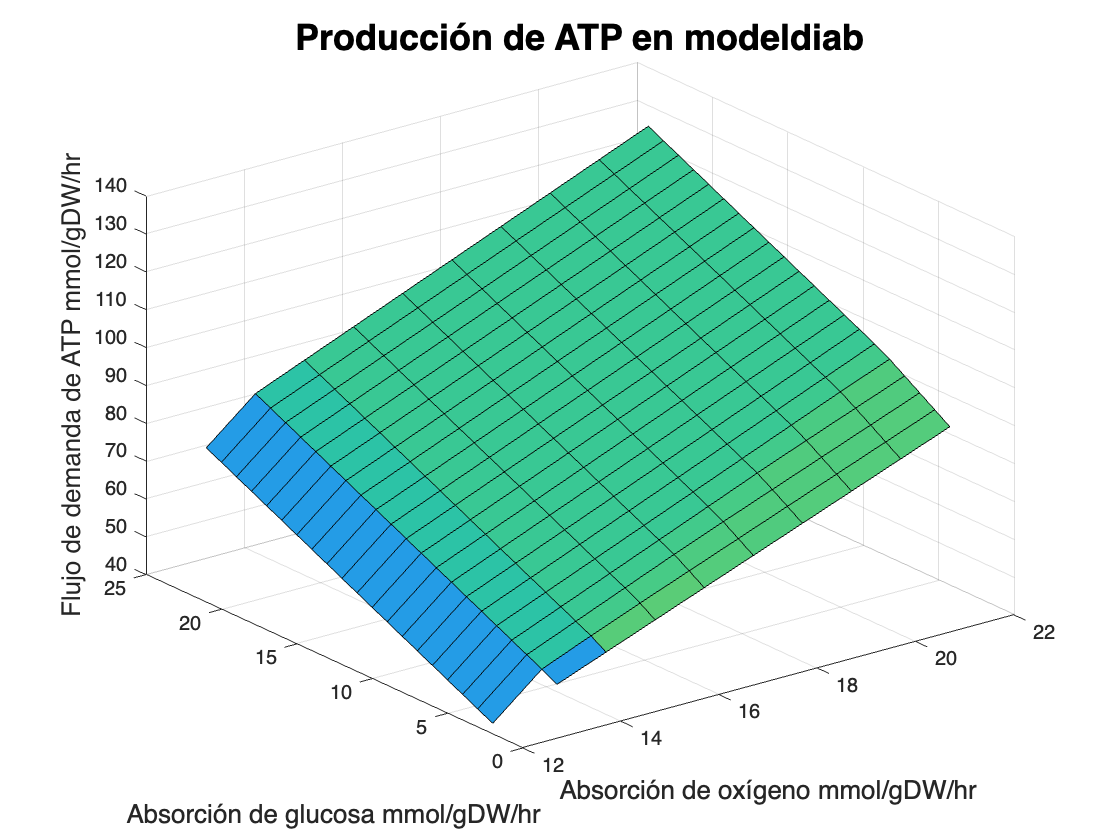

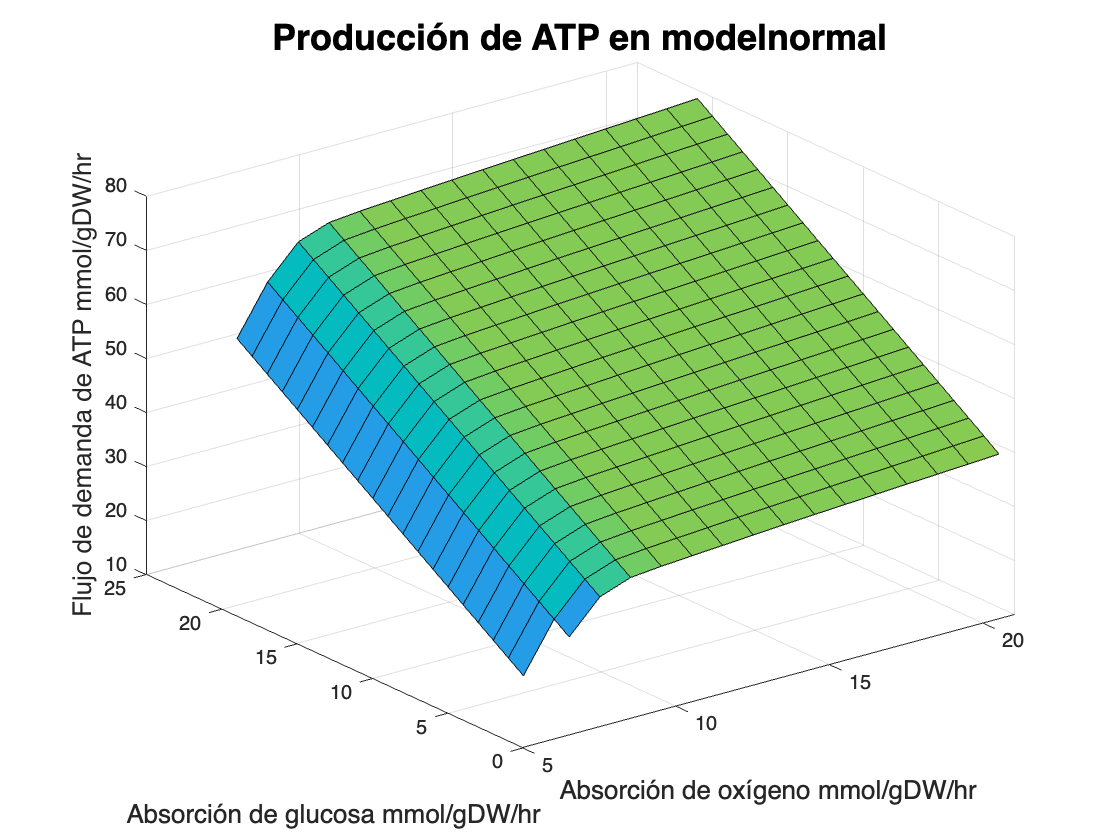

for x=1:length(modelos)
    ATPphppRates = zeros(21);
    model = modelos{x};
    modelN = modelosNames{x};
    model = changeRxnBounds(model, 'EX_glc(e)', -20, 'b'); 
    model = changeRxnBounds(model, 'EX_o2(e)', -17, 'b'); 
for i = 0:20
    for j = 0:20
        modelphpp = changeRxnBounds(model, 'EX_glc(e)', -i, 'b'); 
        modelphpp = changeRxnBounds(modelphpp, 'EX_o2(e)', -j, 'b'); 
        modelphpp = changeObjective(modelphpp, 'DM_atp(c)'); 
        FBAphpp = optimizeCbModel(modelphpp, 'max'); 
        ATPphppRates(i + 1,j + 1) = FBAphpp.f;
    end 
end
    figure;
surfl(ATPphppRates) % 3d plot
xlabel('Absorción de oxígeno mmol/gDW/hr',FontSize=13) 
ylabel('Absorción de glucosa mmol/gDW/hr',FontSize=13) 
zlabel('Flujo de demanda de ATP mmol/gDW/hr',FontSize=13)
 title(sprintf('Producción de ATP en %s', modelN),'FontSIze',18)
end

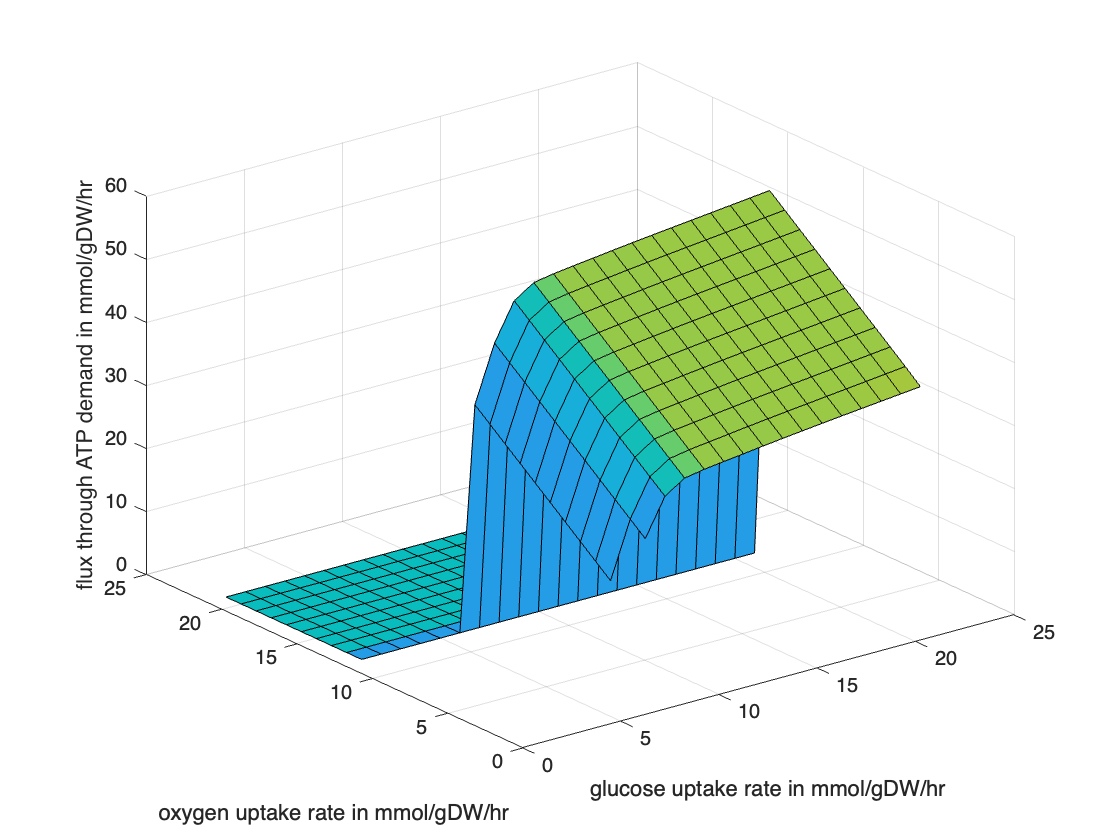

modelow = modelnormal; 
ATPphppRates = zeros(21);
for i = 0:10
    for j = 0:20
        modelow = changeRxnBounds(modelow, 'EX_glc(e)', -i, 'b'); 
        modelow = changeRxnBounds(modelow, 'EX_o2(e)', -j, 'b'); 
        modelow = changeObjective(modelow, 'DM_atp(c)'); 
        FBAphpp = optimizeCbModel(modelow, 'max'); 
        ATPphppRates(i + 1,j + 1) = FBAphpp.f;
    end 
end
surfl(ATPphppRates) % 3d plot
xlabel('glucose uptake rate in mmol/gDW/hr') 
ylabel('oxygen uptake rate in mmol/gDW/hr') 
zlabel('flux through ATP demand in mmol/gDW/hr')

## Bibliografia

- Orth et al, Nat Biotechnol. 2010 Mar;28(3):245-8

- Thiele et al, J Biol Chem. 2005 Mar 25;280(12):11683-95